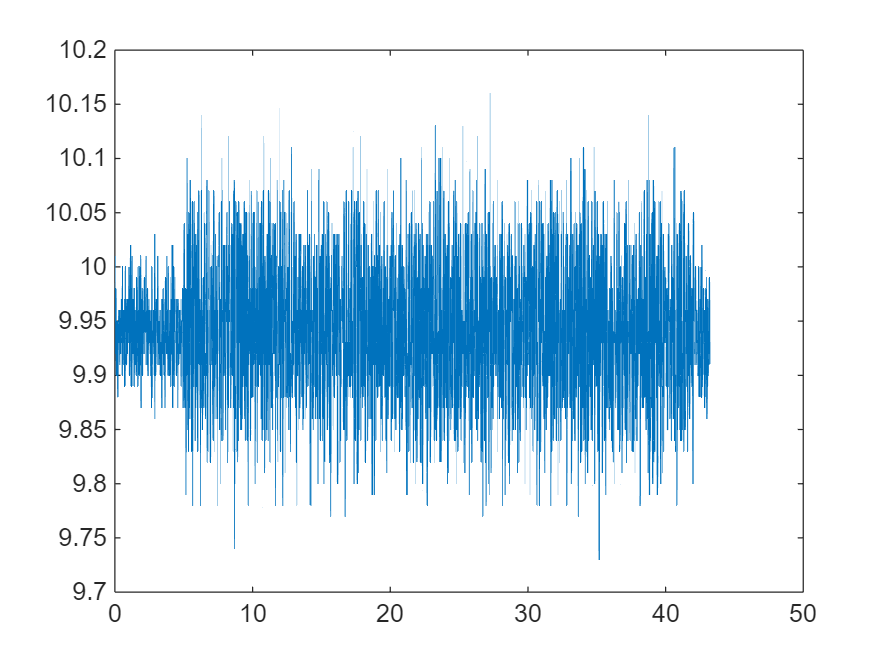

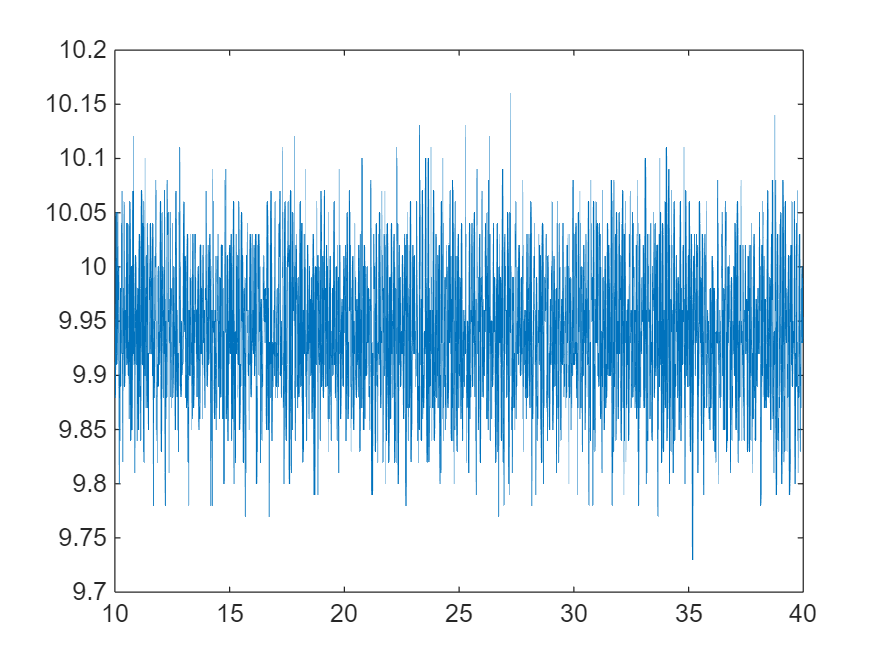

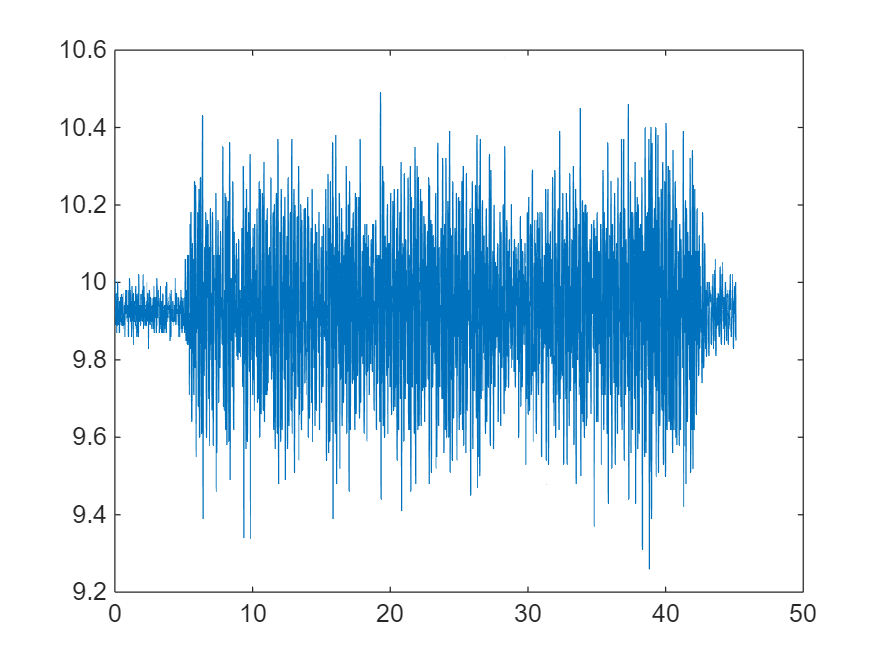

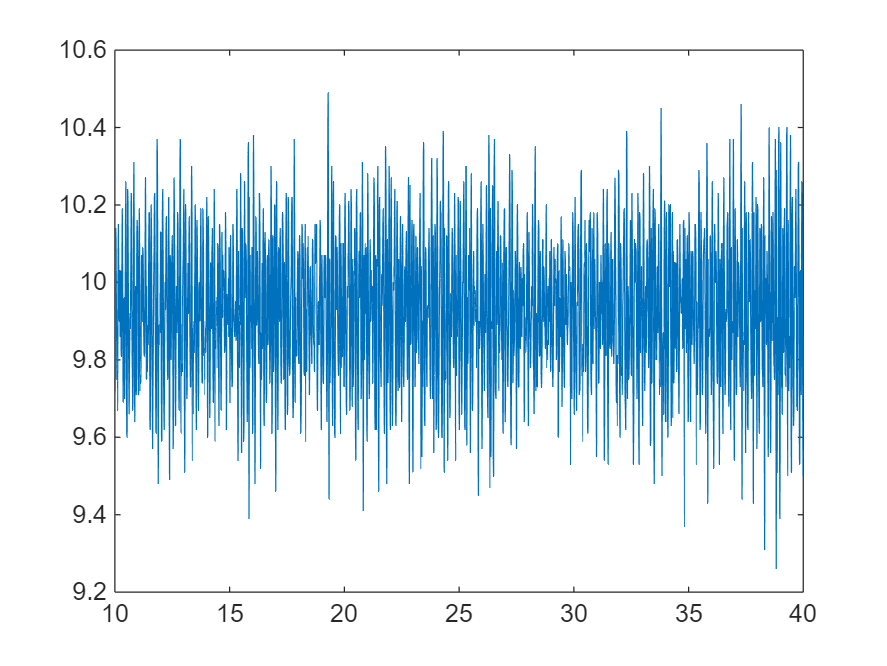

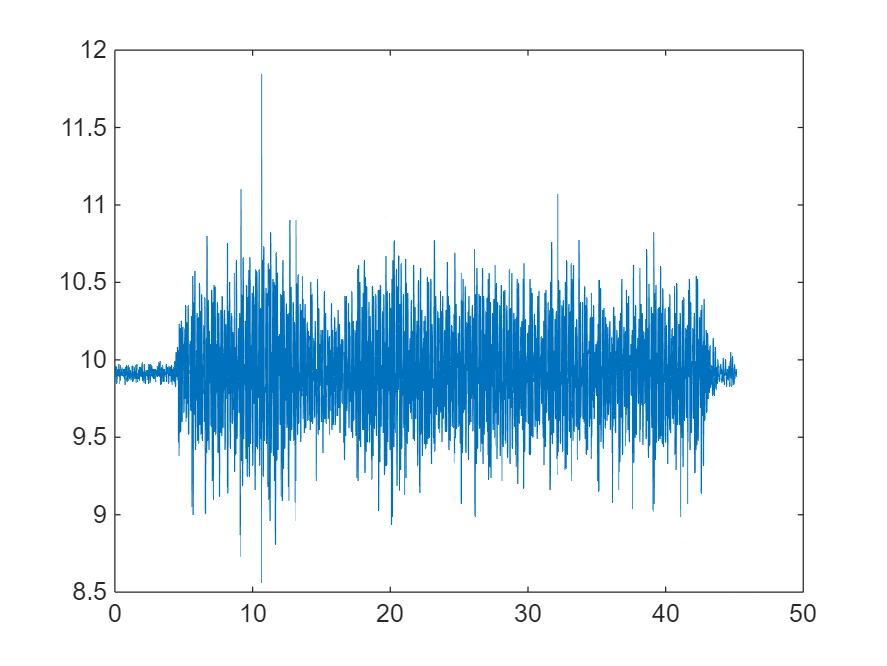

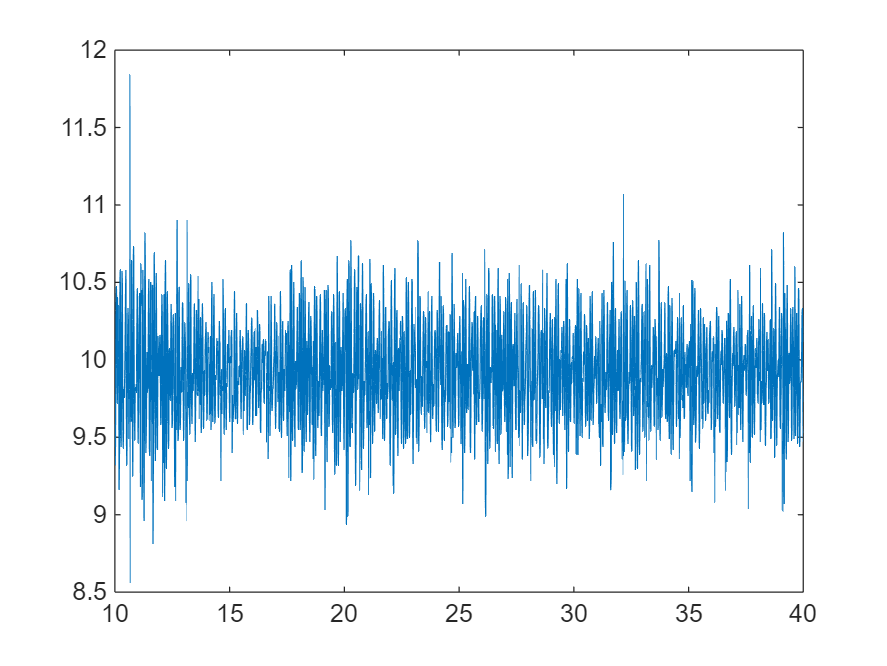

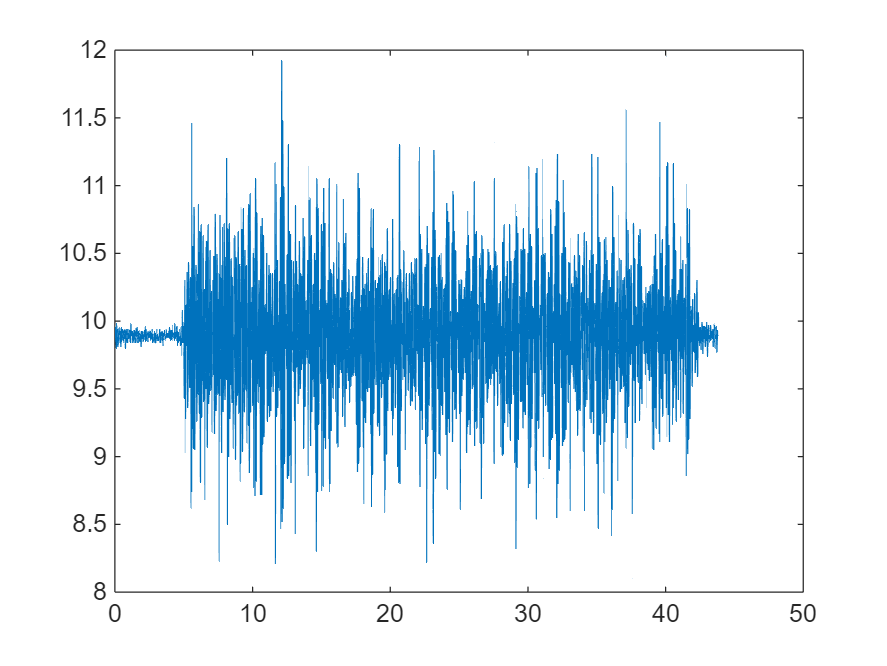

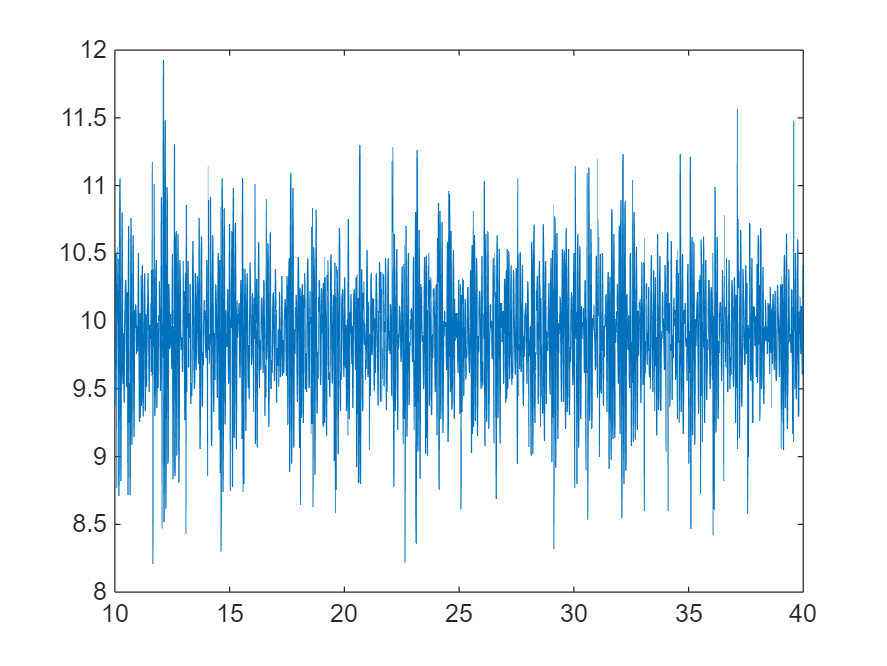

weeks = [20, 26, 30, 34, 40];

volume = [4, 10, 16, 27, 40];
delta_v = [0.5, 2, 3, 4, 10];

data2plot = [];

data2compare = cell(1,length(weeks));

p2pdata = cell(length(weeks),1);

for i = 1:length(weeks)

    filename = strcat('week_',num2str(weeks(i)),'_acc.csv');

    raw_data = readtable(filename,'Delimiter','\t');

    % Take care of header chunk
    raw_time = raw_data{:,1};
    [row, ~] = find(isnan(raw_time));

    if ~isempty(row)
        % double check to make sure nan is from the header instead of data
        if row(end) <= 50

            raw_data = raw_data(row(end)+1:end,:); % clip header
        end
    end
    raw_data(end,:) = [];   % get rid of last line in case of incomplete data log

    % Raw time & data
    time = raw_data{:,1}./1000; % in seconds
    data = raw_data{:,4};

    figure;
    plot(time,data);

    pump_idx = (time >= 10) & (time <= 40);

    time_pump = time(pump_idx);
    data_pump = data(pump_idx);

    figure;
    plot(time_pump,data_pump);

    ts = 0.03;
    fs = 1/ts;

    rs_time = 1:ts:350;

    [~,end_idx] = min(abs(rs_time - time_pump(end)));
    [~,stt_idx] = min(abs(rs_time - time_pump(1)));


    rs_time  = rs_time(stt_idx:end_idx);
    rs_data = interp1(time,data,rs_time);


    % High pass to try to remove baseline

    cutoff_freq = 0.3;    % Cutoff frequency in Hz
    filter_order = 4;    % Filter order (adjust as needed)

    % lpf = designfilt('lowpassiir', ...
    %     'FilterOrder', filter_order, ...
    %     'HalfPowerFrequency', cutoff_freq, ...
    %     'SampleRate', fs, ...
    %     'DesignMethod', 'butter');

    [b, a] = butter(filter_order, cutoff_freq/(fs/2), 'high');
    hp_data= filtfilt(b, a, rs_data);

    figure;
    plot(rs_time,hp_data)

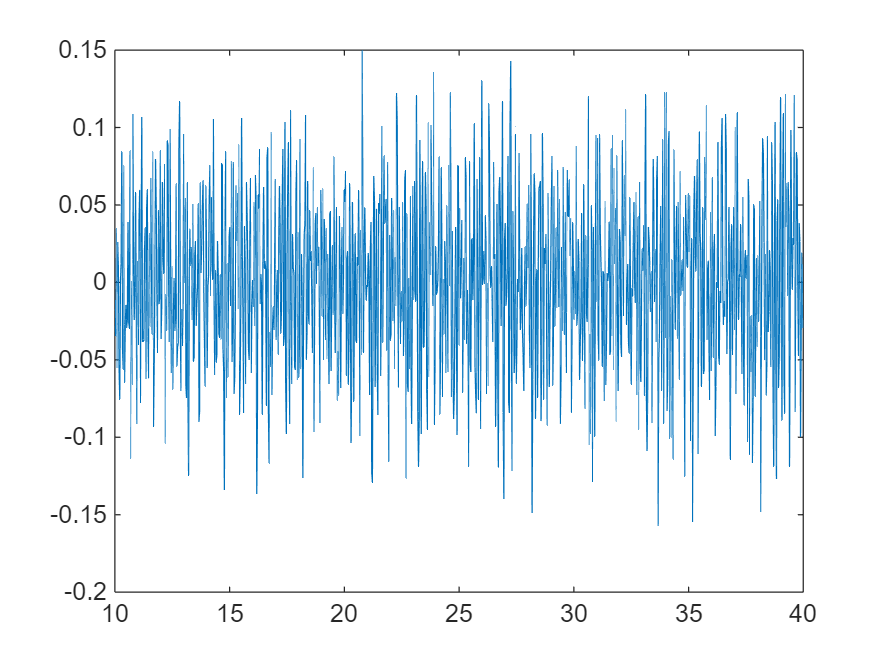

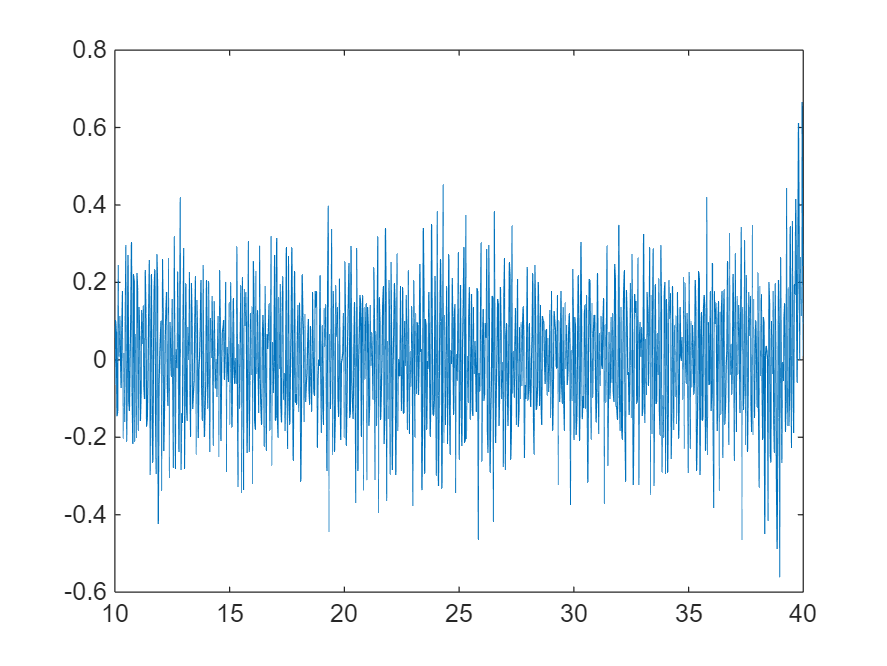

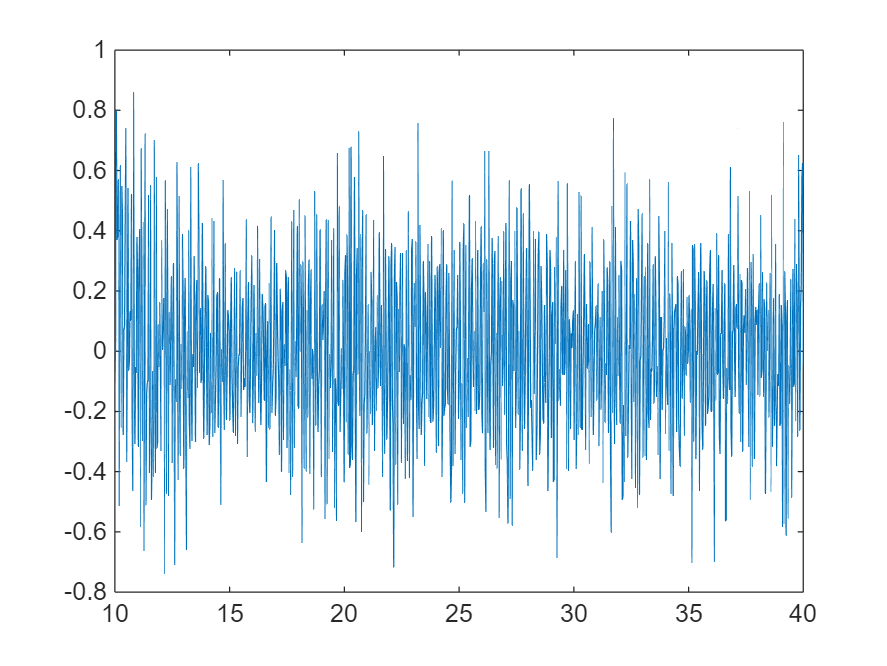

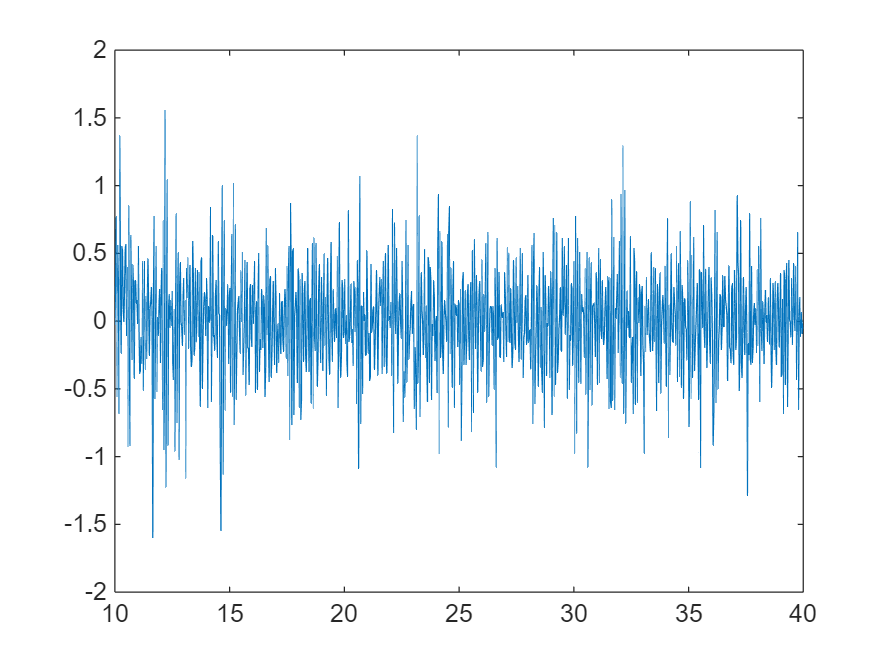

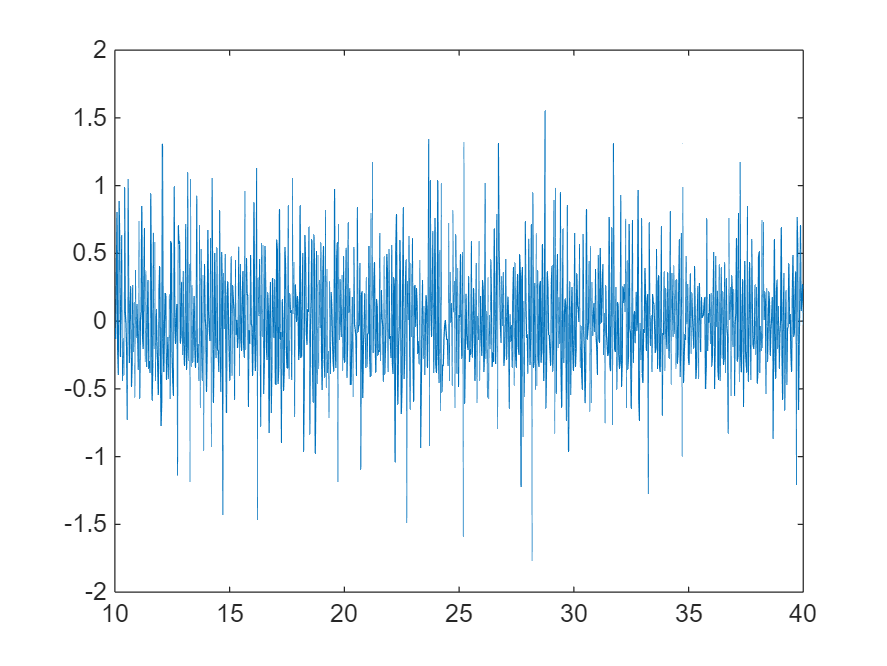

    % Low pass to try to remove noise

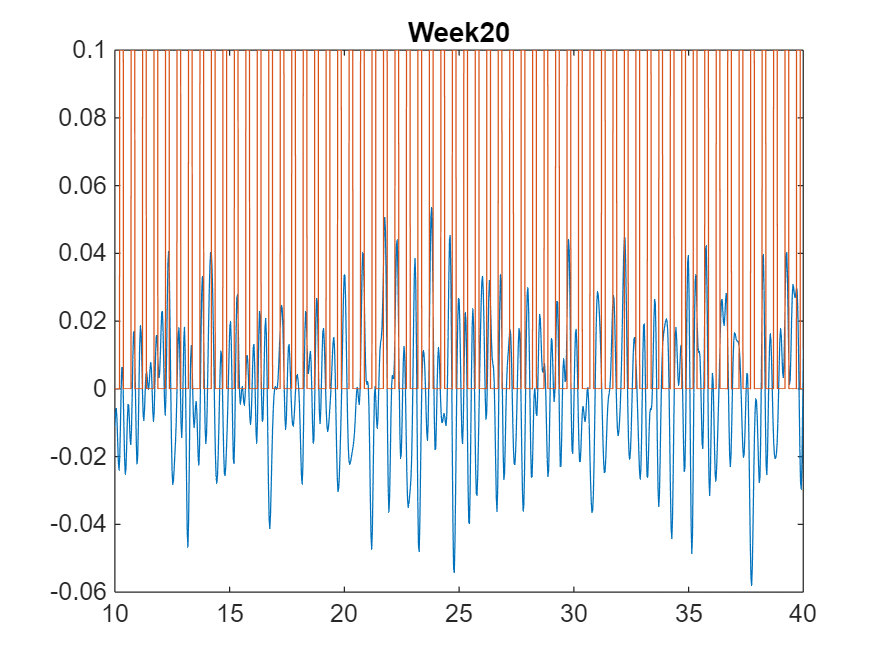

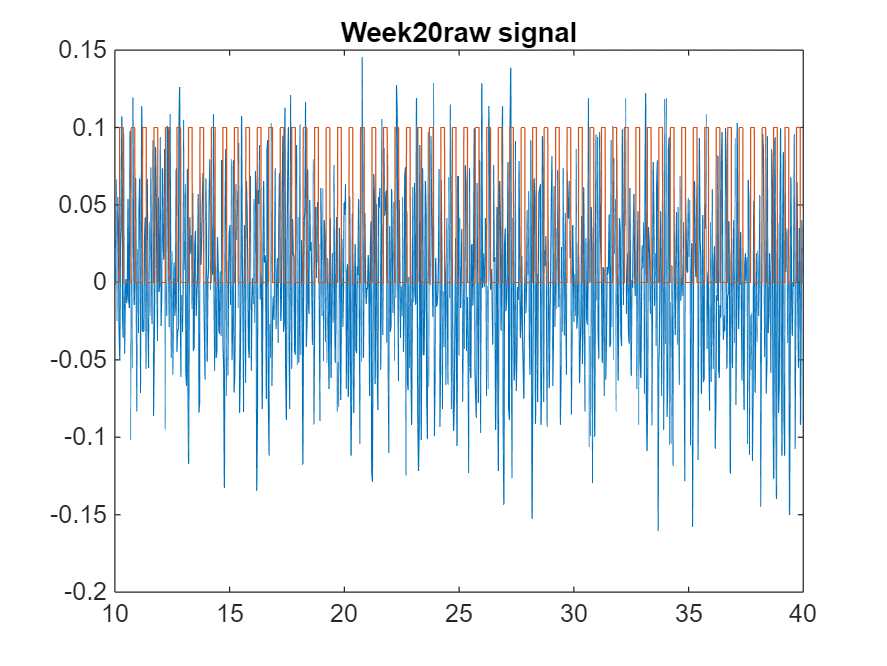

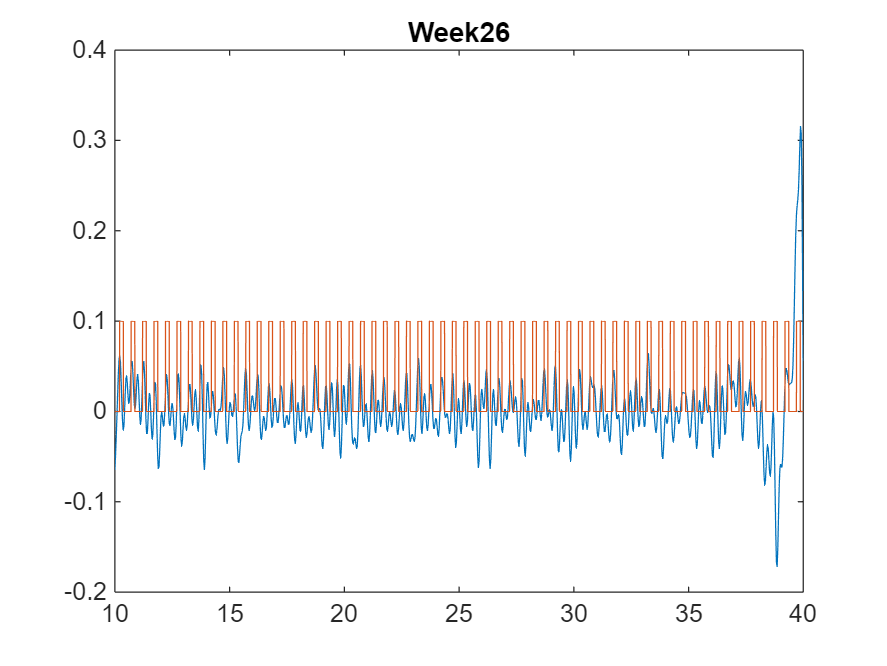

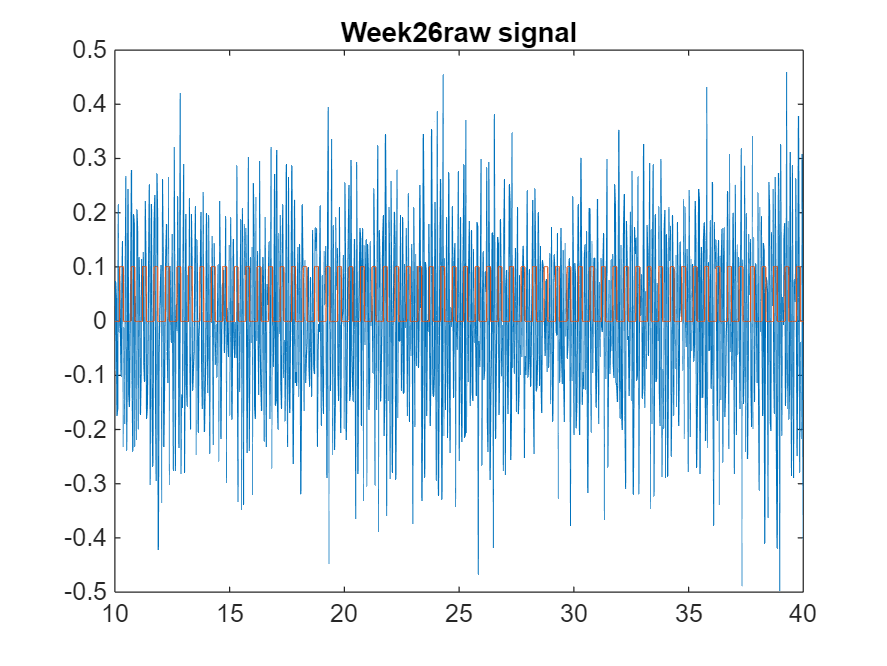

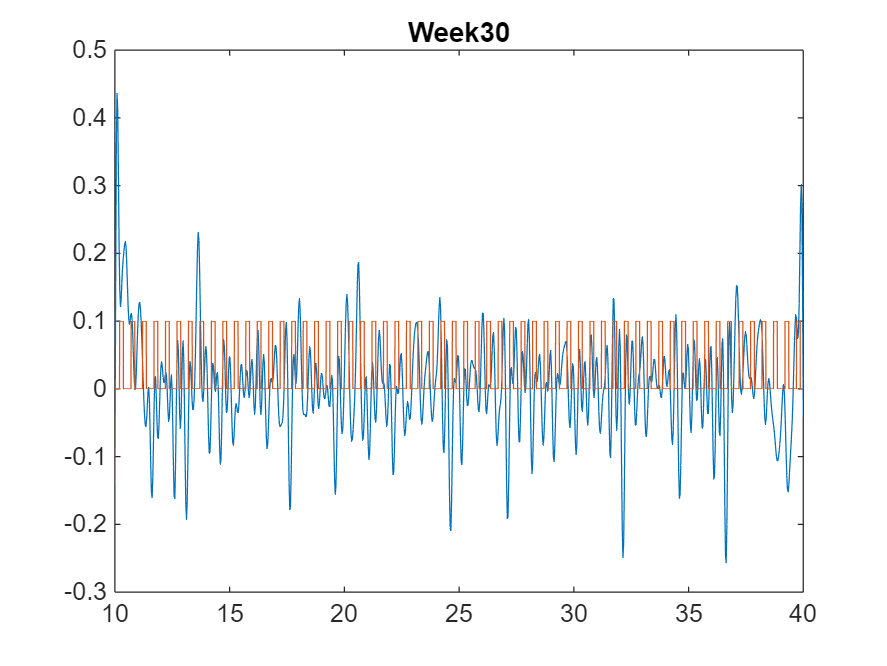

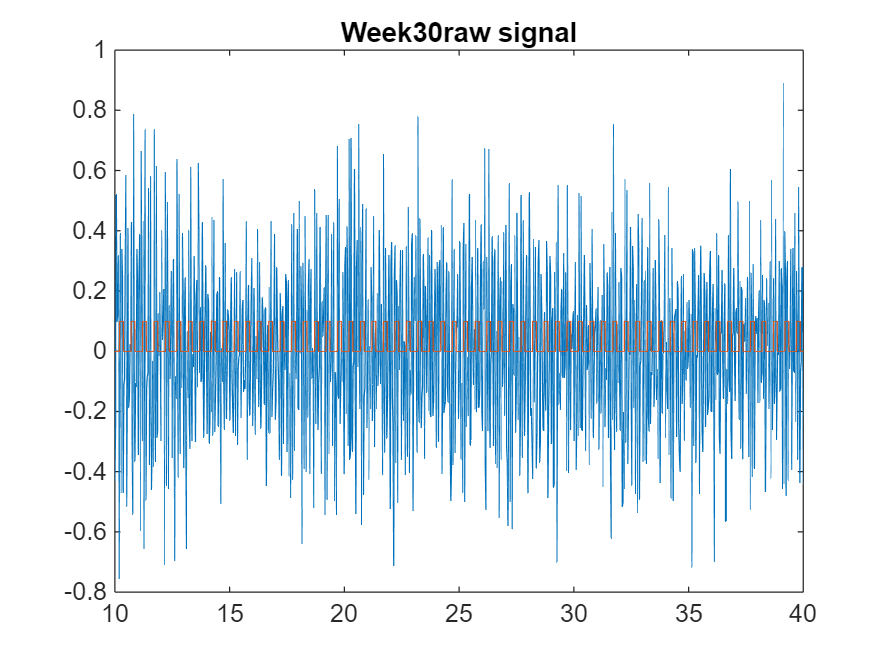

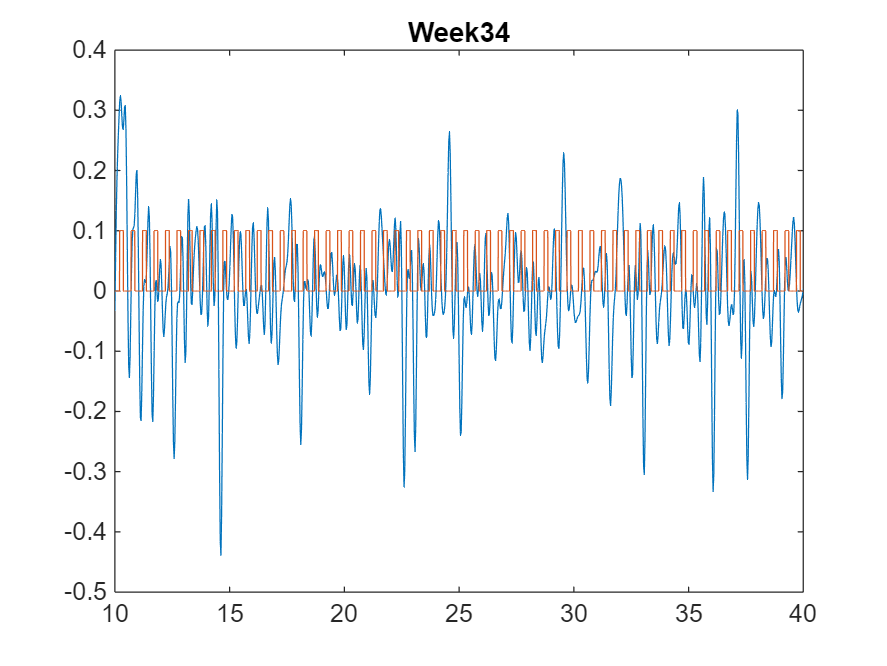

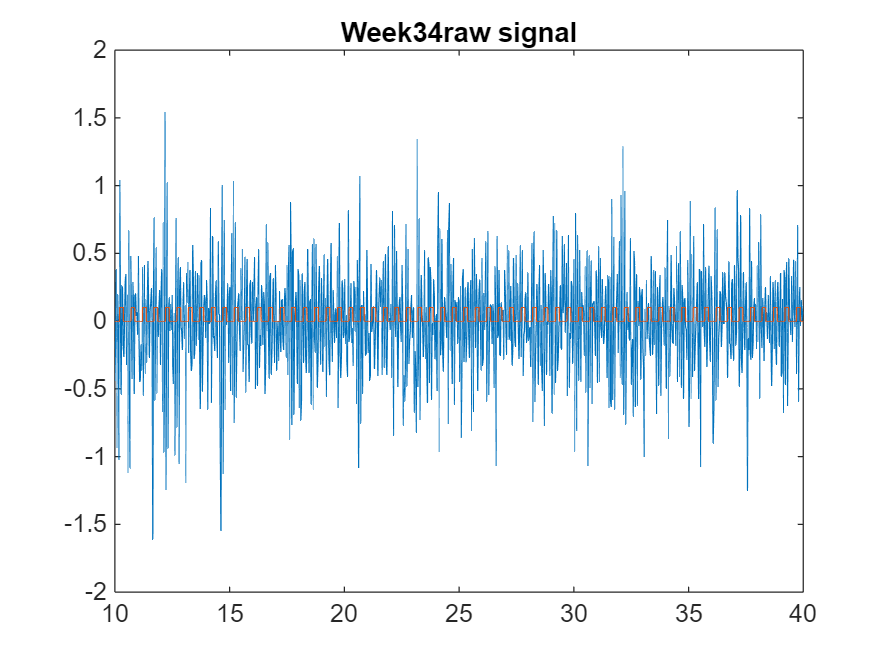


    cutoff_freq = 4;    % Cutoff frequency in Hz
    filter_order = 5;    % Filter order (adjust as needed)

    % lpf = designfilt('lowpassiir', ...
    %     'FilterOrder', filter_order, ...
    %     'HalfPowerFrequency', cutoff_freq, ...
    %     'SampleRate', fs, ...
    %     'DesignMethod', 'butter');

    [b, a] = butter(filter_order, cutoff_freq/(fs/2), 'low');
    bp_data= filtfilt(b, a, hp_data);

    act_time = 8:0.005:42;
    act_time(end) = [];
    act_time = act_time-0.13;
    single_act_data = [zeros(1,67),ones(1,33)]*0.1;
    act_data = repmat(single_act_data,1,68);

    figure;
    plot(rs_time,bp_data)
    hold on
    plot(act_time,act_data)
    hold off
    xlim([10 40])
    title_txt = strcat('Week ',num2str(weeks(i)));
    title(title_txt)

    figure;
    plot(rs_time,rs_data-mean(rs_data))
    hold on
    plot(act_time,act_data)
    hold off
    xlim([10 40])
    title_txt = strcat('Week ',num2str(weeks(i)),'raw signal');
    title(title_txt)

    clip_data = bp_data(rs_time>20&rs_time<30);
    clip_time = rs_time(rs_time>20&rs_time<30);


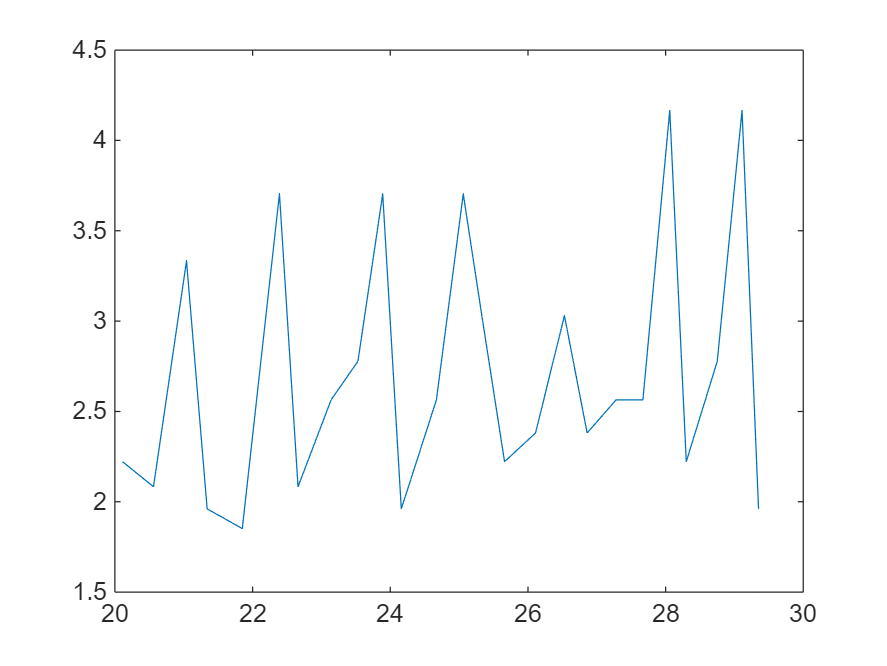

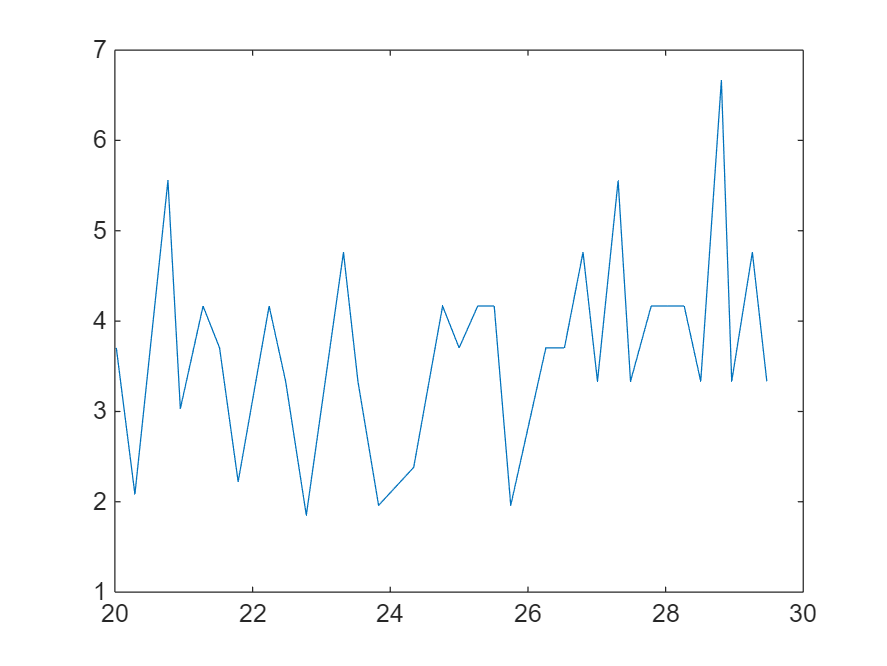

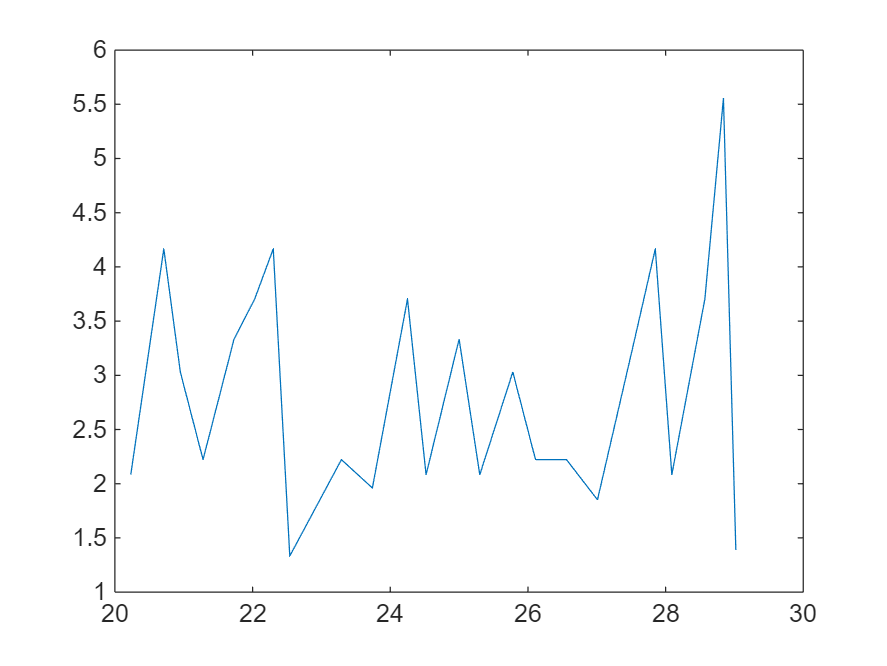

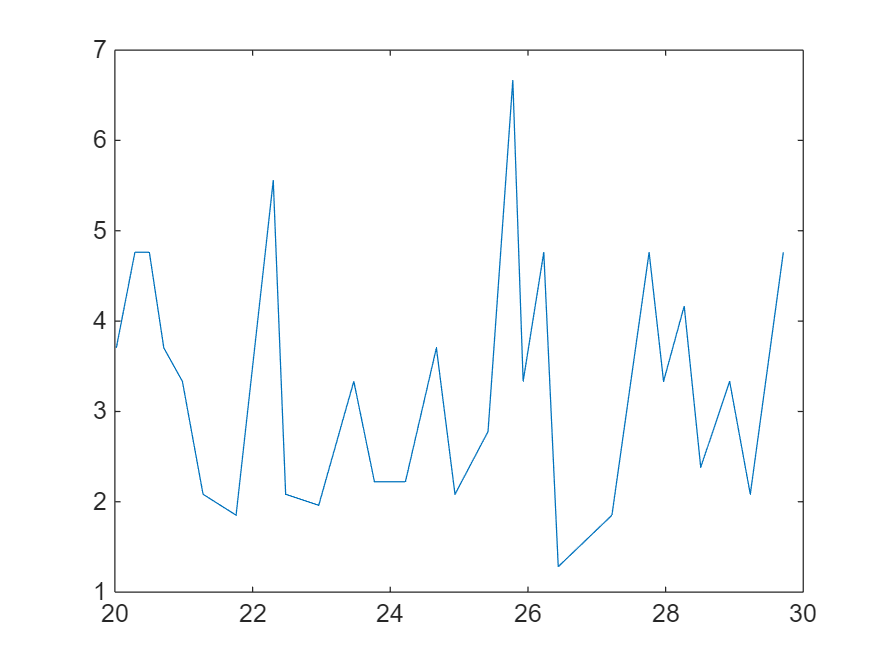

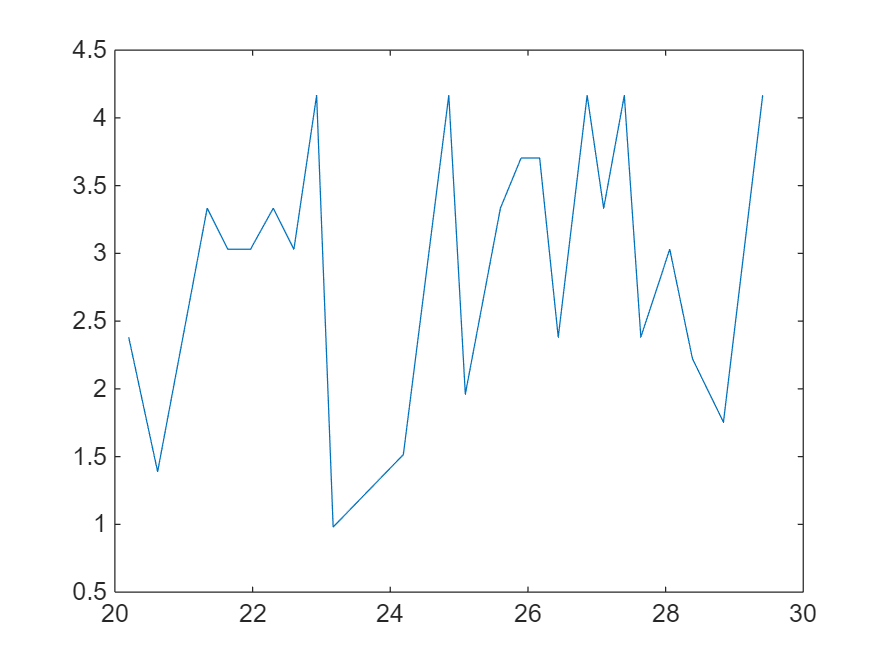

    % Frequency calculation
    cross_idx = find(clip_data(1:end-1).*clip_data(2:end) < 0 );
    time_cross = clip_time(cross_idx);
    data_cross = clip_data(cross_idx);
    pos_cross_idx = find(data_cross > 0);
    pos_time_cross = time_cross(pos_cross_idx);
    cross_time_diff = pos_time_cross(2:end) - pos_time_cross(1:end-1);
    cross_freq = 1./ cross_time_diff;
    figure;
    plot(pos_time_cross(1:end-1),cross_freq)


    % magnitude
    RMS = sqrt(mean(clip_data.^2))

    % p2p
    [pk_vals, pk_locs] = findpeaks(clip_data, clip_time,'MinPeakHeight', 0.005);
    [tr_vals_neg, tr_locs] = findpeaks(-clip_data, clip_time,'MinPeakHeight', 0.005);
    tr_vals = -tr_vals_neg;

    if tr_locs(1) < pk_locs(1)
        tr_locs(1) = []; tr_vals(1) = [];
    end

    N = min(numel(pk_locs), numel(tr_locs));
    pk_locs = pk_locs(1:N);
    pk_vals = pk_vals(1:N);
    tr_locs = tr_locs(1:N);
    tr_vals = tr_vals(1:N);

    p2p = pk_vals - tr_vals;
    mean_p2p = mean(p2p)
    std_p2p = std(p2p)

    wk_label = ones(length(p2p),1) .* weeks(i);
    vini_label = ones(length(p2p),1) .* volume(i);
    vdelta_label = ones(length(p2p),1) .* delta_v(i);



    p2pdata{i} = [wk_label,vini_label,vdelta_label, p2p'];

    data2save = [weeks(i),volume(i),delta_v(i),RMS,mean_p2p,std_p2p];
    data2plot = [data2plot;data2save];
    data2compare{i} = p2p;

end

RMS = 0.0214

mean_p2p = 0.0540

std_p2p = 0.0177

RMS = 0.0242

mean_p2p = 0.0580

std_p2p = 0.0214

RMS = 0.0627

mean_p2p = 0.1449

std_p2p = 0.0654

RMS = 0.0824

mean_p2p = 0.1545

std_p2p = 0.0973

RMS = 0.1116

mean_p2p = 0.2246

std_p2p = 0.1348

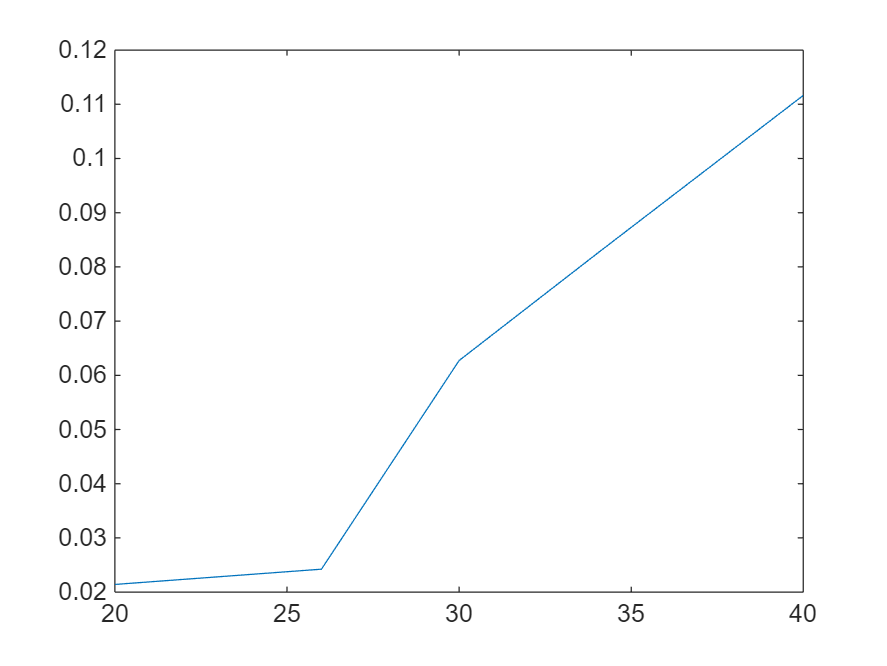

figure;
plot(data2plot(:,1),data2plot(:,4))

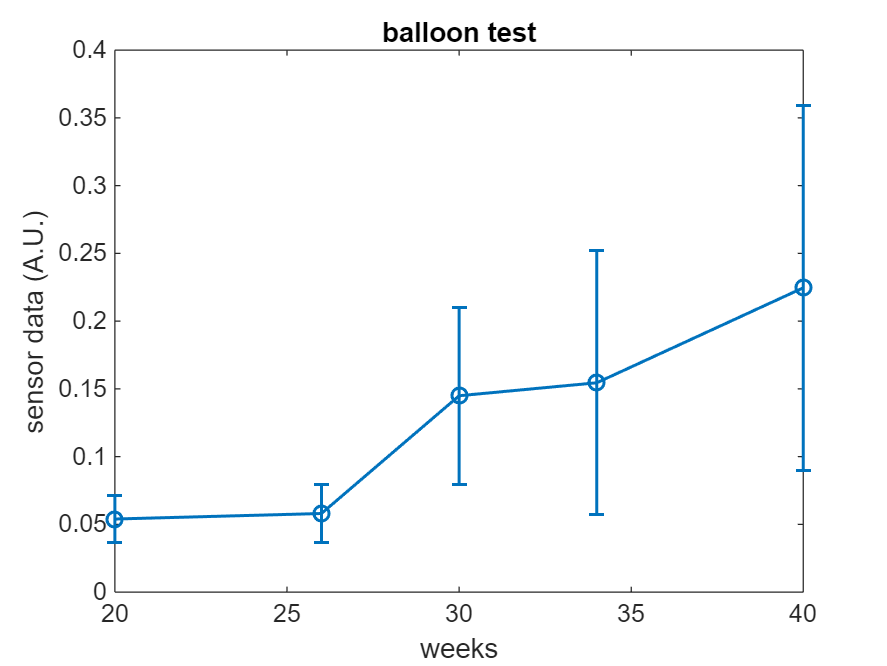


figure;
errorbar(data2plot(:,1),data2plot(:,5), data2plot(:,6), 'o-','LineWidth',1.2,'MarkerSize',6);
xlabel('weeks')
ylabel('sensor data (A.U.)')
title('balloon test')

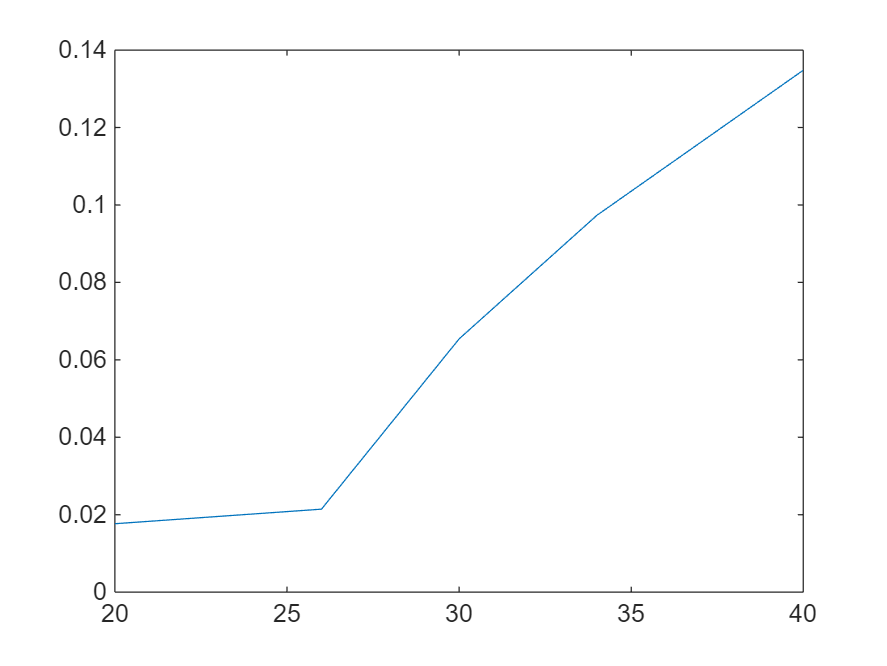



figure;
plot(data2plot(:,1),data2plot(:,6))

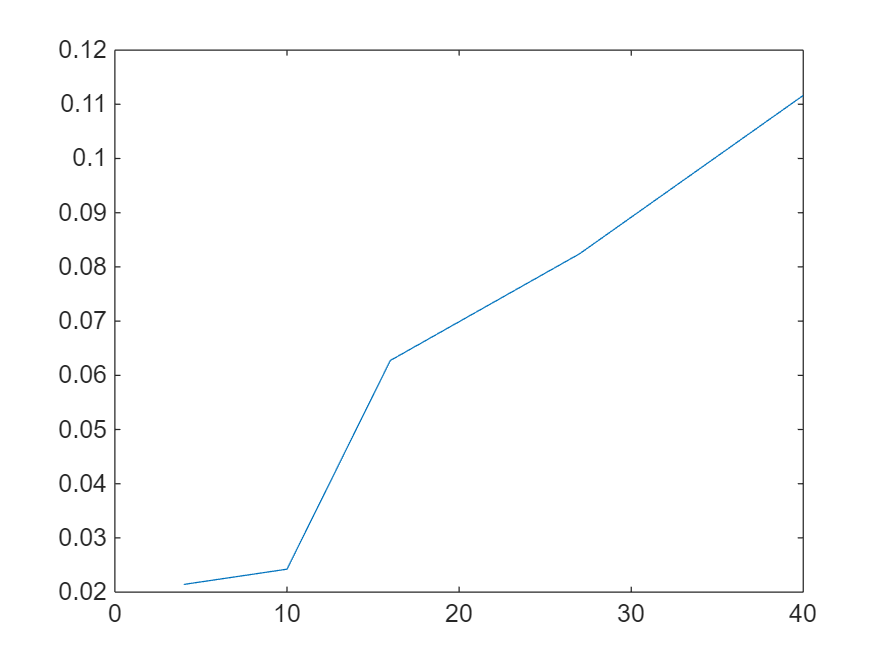

figure;
plot(data2plot(:,2),data2plot(:,4))

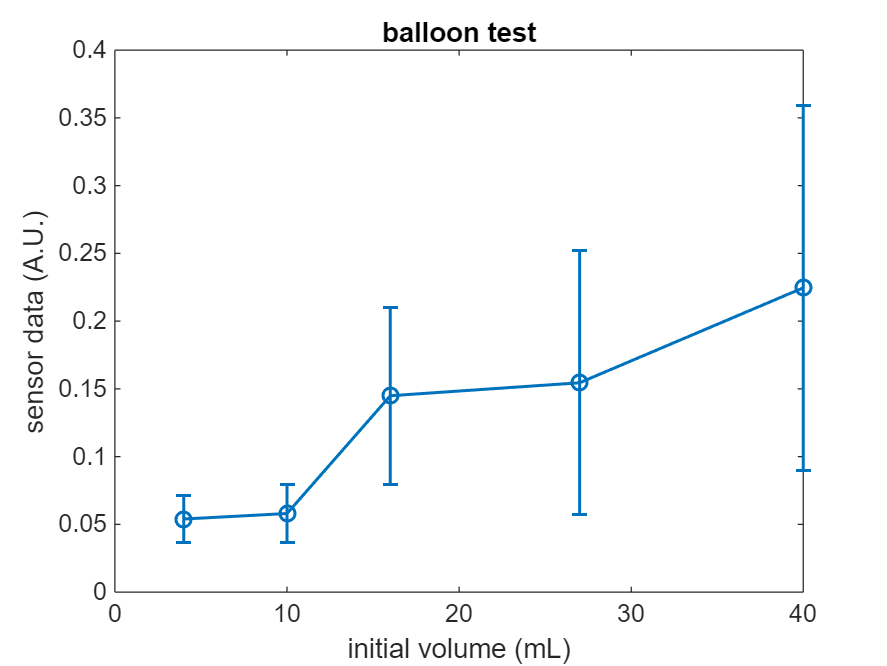


figure;
errorbar(data2plot(:,2),data2plot(:,5), data2plot(:,6), 'o-','LineWidth',1.2,'MarkerSize',6);
xlabel('initial volume (mL)')
ylabel('sensor data (A.U.)')
title('balloon test')

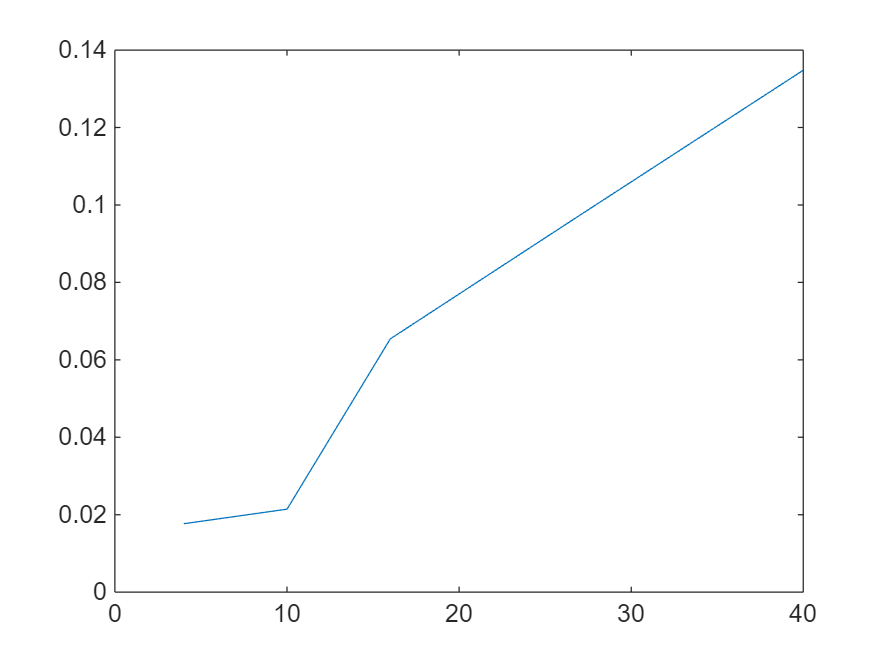



figure;
plot(data2plot(:,2),data2plot(:,6))

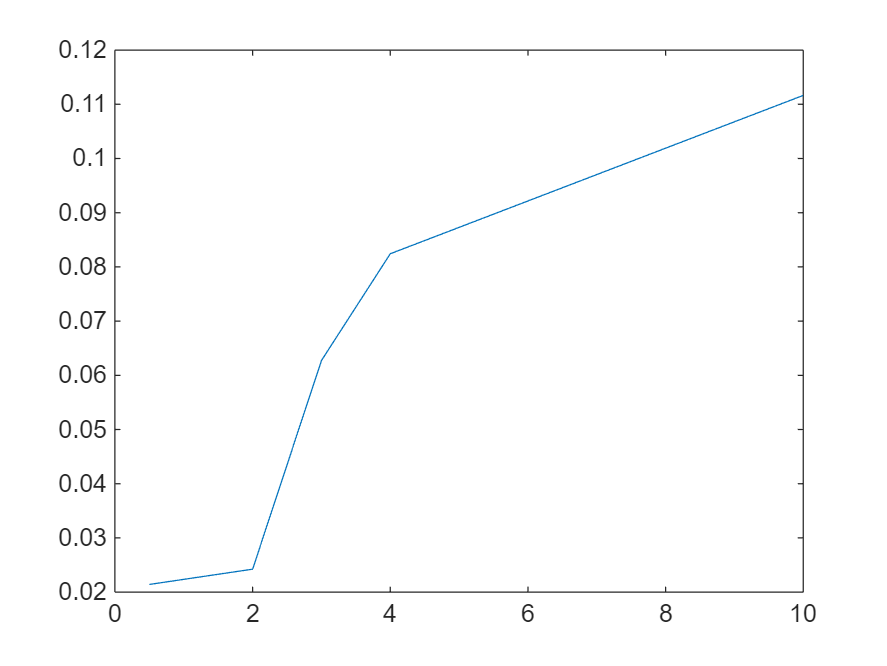

figure;
plot(data2plot(:,3),data2plot(:,4))

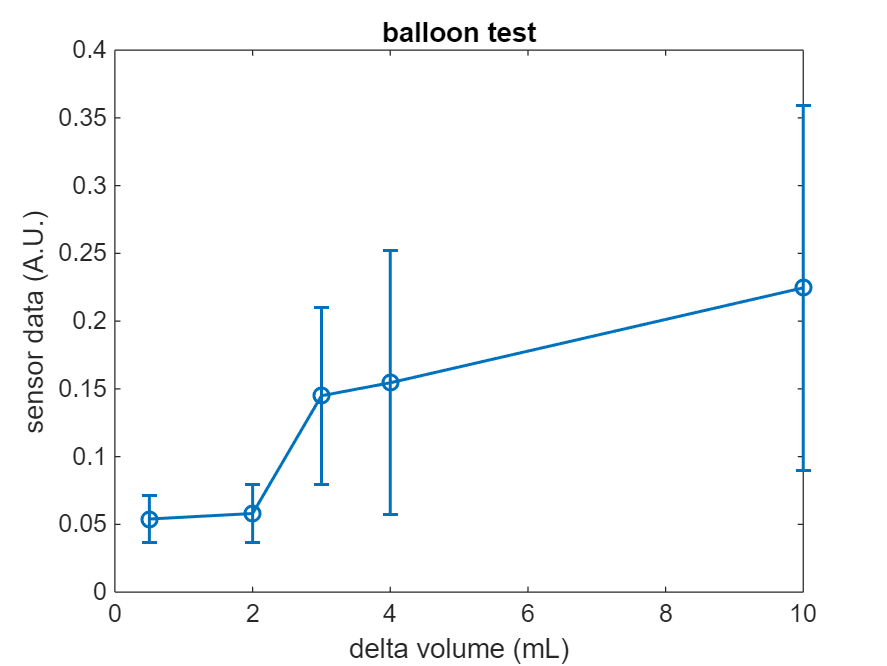


figure;
errorbar(data2plot(:,3),data2plot(:,5), data2plot(:,6), 'o-','LineWidth',1.2,'MarkerSize',6);
xlabel('delta volume (mL)')
ylabel('sensor data (A.U.)')
title('balloon test')

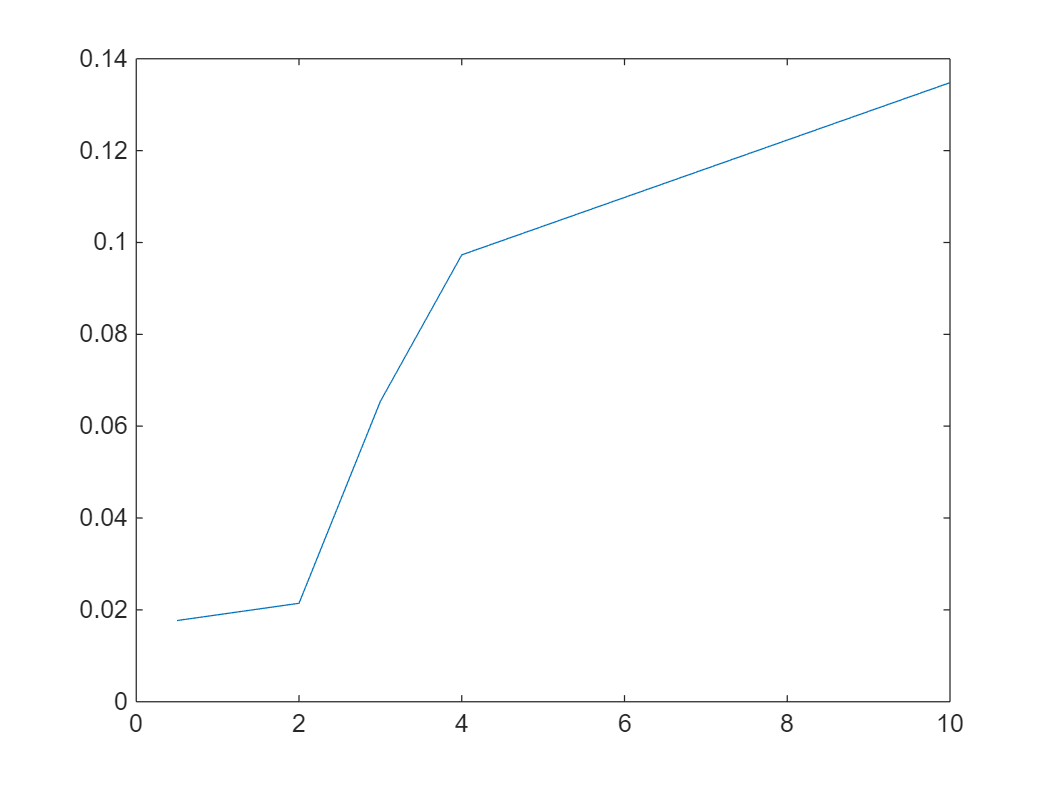



figure;
plot(data2plot(:,3),data2plot(:,6))

numGroups = numel(data2compare);
pairs    = nchoosek(1:numGroups,2);
numPairs = size(pairs,1);

p_raw  = nan(numPairs,1);

for k = 1:numPairs
    i = pairs(k,1);
    j = pairs(k,2);
    [~, p_raw(k)] = ttest2(data2compare{i}, data2compare{j}, 'Vartype','unequal');
end

p_bonf = min(p_raw * numPairs, 1);

results = table(pairs(:,1), pairs(:,2), p_raw, p_bonf, ...
    'VariableNames', {'Group1','Group2','p_raw','p_bonf'});

disp(results);

    Group1    Group2      p_raw         p_bonf  
    ______    ______    __________    __________

      1         2          0.44371             1
      1         3       3.0156e-07    3.0156e-06
      1         4       6.2726e-06    6.2726e-05
      1         5       9.0627e-07    9.0627e-06
      2         3       6.5693e-07    6.5693e-06
      2         4       1.1844e-05    0.00011844
      2         5       1.3332e-06    1.3332e-05
      3         4          0.66987             1
      3         5         0.010429       0.10429
      4         5         0.033822       0.33822



mdl_wk = fitlm(data2plot(:,1),data2plot(:,5))

mdl_wk = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE        tStat      pValue 
                   _________    _________    ______    ________

    (Intercept)     -0.14336     0.049829    -2.877    0.063684
    x1             0.0090185    0.0016197    5.5679    0.011432


Number of observations: 5, Error degrees of freedom: 3
Root Mean Squared Error: 0.0247
R-squared: 0.912,  Adjusted R-Squared: 0.882
F-statistic vs. constant model: 31, p-value = 0.0114


mdl_vini = fitlm(data2plot(:,2),data2plot(:,5))

mdl_vini = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate         SE        tStat      pValue 
                   _________    __________    ______    ________

    (Intercept)     0.034087      0.020029    1.7018     0.18734
    x1             0.0047995    0.00086176    5.5694    0.011424


Number of observations: 5, Error degrees of freedom: 3
Root Mean Squared Error: 0.0247
R-squared: 0.912,  Adjusted R-Squared: 0.882
F-statistic vs. constant model: 31, p-value = 0.0114


mdl_vdelta = fitlm(data2plot(:,3),data2plot(:,5))

mdl_vdelta = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat      pValue 
                   ________    _________    ______    ________

    (Intercept)    0.056722     0.023201    2.4448    0.092106
    x1              0.01807    0.0045633    3.9599    0.028755


Number of observations: 5, Error degrees of freedom: 3
Root Mean Squared Error: 0.0333
R-squared: 0.839,  Adjusted R-Squared: 0.786
F-statistic vs. constant model: 15.7, p-value = 0.0288


overallWkData = [];
for i = 1:length(p2pdata)
    overallWkData = [overallWkData;p2pdata{i}];
end

mdl_wk_all = fitlm(log(overallWkData(:,1)),overallWkData(:,4))

mdl_wk_all = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)    -0.74921     0.10547    -7.1035    6.6399e-11
    x1              0.25911    0.031146     8.3191    9.2618e-14


Number of observations: 135, Error degrees of freedom: 133
Root Mean Squared Error: 0.0831
R-squared: 0.342,  Adjusted R-Squared: 0.337
F-statistic vs. constant model: 69.2, p-value = 9.26e-14

mdl_vini_all = fitlm(log(overallWkData(:,2)),overallWkData(:,4))

mdl_vini_all = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE         tStat       pValue  
                   _________    _________    _______    __________

    (Intercept)    -0.077113     0.026028    -2.9627     0.0036132
    x1              0.075102    0.0092387     8.1291    2.6474e-13


Number of observations: 135, Error degrees of freedom: 133
Root Mean Squared Error: 0.0837
R-squared: 0.332,  Adjusted R-Squared: 0.327
F-statistic vs. constant model: 66.1, p-value = 2.65e-13

mdl_vdelta_all = fitlm(log(overallWkData(:,3)),overallWkData(:,4))

mdl_vdelta_all = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)     0.06688     0.010519    6.3579    3.0266e-09
    x1             0.060486    0.0077272    7.8276    1.3803e-12


Number of observations: 135, Error degrees of freedom: 133
Root Mean Squared Error: 0.0848
R-squared: 0.315,  Adjusted R-Squared: 0.31
F-statistic vs. constant model: 61.3, p-value = 1.38e-12

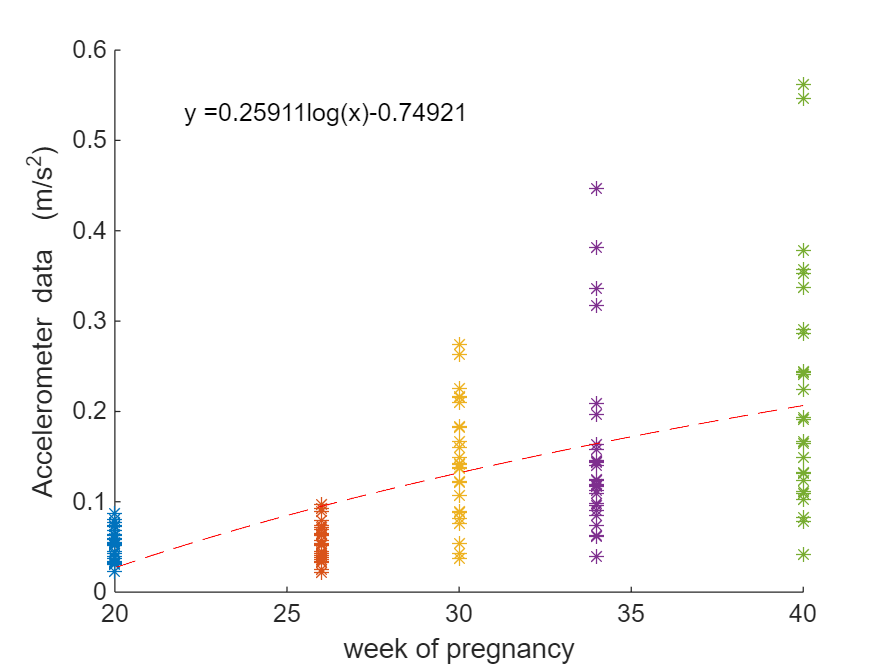


x = 0:0.01:50;
y_wk = log(x).*mdl_wk_all.Coefficients{"x1","Estimate"} + mdl_wk_all.Coefficients{'(Intercept)',"Estimate"};
y_vini = log(x).*mdl_vini_all.Coefficients{"x1","Estimate"} + mdl_vini_all.Coefficients{'(Intercept)',"Estimate"};
y_vdelta = log(x).*mdl_vdelta_all.Coefficients{"x1","Estimate"} + mdl_vdelta_all.Coefficients{'(Intercept)',"Estimate"};

equation_wk = strcat('y = ',num2str(mdl_wk_all.Coefficients{"x1","Estimate"}),'log(x) ',num2str(mdl_wk_all.Coefficients{'(Intercept)',"Estimate"}));
R_sq_wk = strcat('R^2 = ',num2str(mdl_wk_all.Rsquared.Ordinary));

equation_vini = strcat('y = ',num2str(mdl_vini_all.Coefficients{"x1","Estimate"}),'log(x) + ',num2str(mdl_vini_all.Coefficients{'(Intercept)',"Estimate"}));
R_sq_vini = strcat('R^2 = ',num2str(mdl_vini_all.Rsquared.Ordinary));

equation_vdelta = strcat('y = ',num2str(mdl_vdelta_all.Coefficients{"x1","Estimate"}),'log(x) + ',num2str(mdl_vdelta_all.Coefficients{'(Intercept)',"Estimate"}));
R_sq_vdelta = strcat('R^2 = ',num2str(mdl_vdelta_all.Rsquared.Ordinary));

figure;

hold on
for i = 1:length(p2pdata)
    plot(p2pdata{i}(:,1),p2pdata{i}(:,4),'*')
end
plot(x,y_wk,'r--')
text(22, 0.53, equation_wk);
% text(22, 0.48, R_sq_wk);
hold off
xlabel('week of pregnancy')
ylabel('Accelerometer data  (m/s^2)')
xlim([20 40])
ylim([0 0.6])

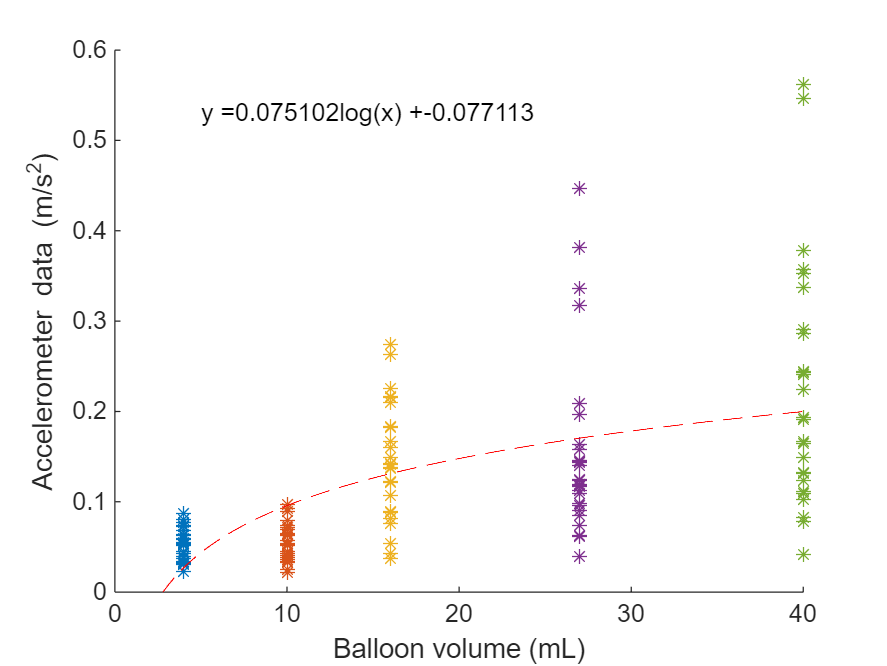


figure;
hold on
for i = 1:length(p2pdata)
    plot(p2pdata{i}(:,2),p2pdata{i}(:,4),'*')
end
plot(x,y_vini,'r--')
text(5, 0.53, equation_vini);
% text(5, 0.48, R_sq_vini);
hold off
xlabel('Balloon volume (mL)')
ylabel('Accelerometer data (m/s^2)')
xlim([0 40])
ylim([0 0.6])

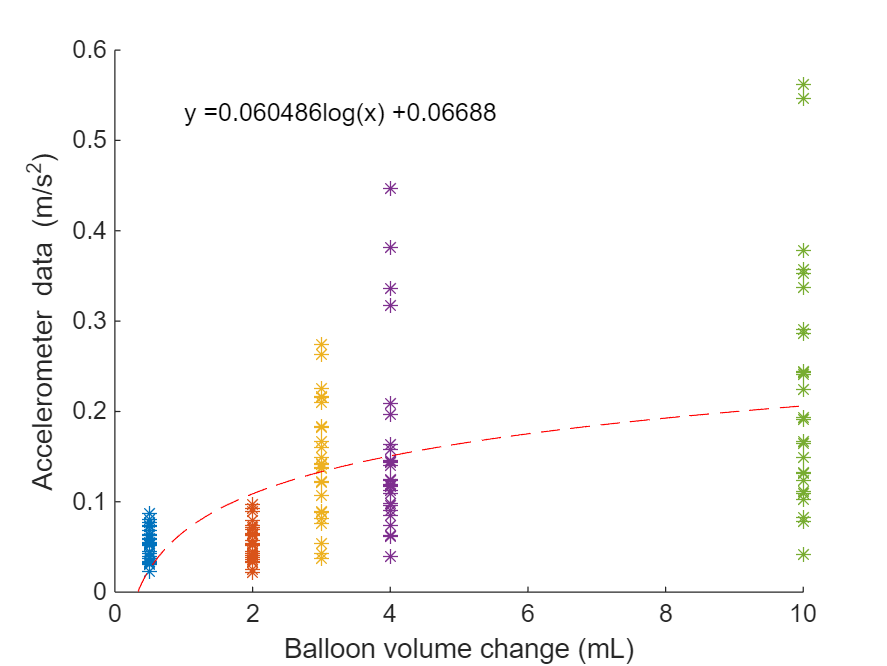


figure;
hold on
for i = 1:length(p2pdata)
    plot(p2pdata{i}(:,3),p2pdata{i}(:,4),'*')
end
plot(x,y_vdelta,'r--')
text(1, 0.53, equation_vdelta);
% text(1, 0.48, R_sq_vdelta);
hold off
xlabel('Balloon volume change (mL)')
ylabel('Accelerometer data (m/s^2)')
xlim([0 10])
ylim([0 0.6])

corr_wk = corr(overallWkData(:,1),overallWkData(:,4))

corr_wk = 0.5993

corr_vini = corr(overallWkData(:,2),overallWkData(:,4))

corr_vini = 0.6008

corr_vdelta = corr(overallWkData(:,3),overallWkData(:,4))

corr_vdelta = 0.5741


wk_ideal = [];
vini_ideal = [];
vdelta_ideal = [];

wk_MAerror = 0;
vini_MAerror = 0;
vdelta_MAerror = 0;

wk_RMSerror = 0;
vini_RMSerror = 0;
vdelta_RMSerror = 0;

for i = 1:length(weeks)
    wk_ideal = y_wk(x==weeks(i));
    vini_ideal = y_vini(x==volume(i));
    vdelta_ideal = y_vdelta(x==delta_v(i));
    wk_MAerror = wk_MAerror + sum(abs(p2pdata{i}(:,4)-wk_ideal));
    vini_MAerror = vini_MAerror + sum(abs(p2pdata{i}(:,4)-vini_ideal));
    vdelta_MAerror = vdelta_MAerror + sum(abs(p2pdata{i}(:,4)-vdelta_ideal));

    wk_RMSerror = wk_RMSerror + sum((p2pdata{i}(:,4)-wk_ideal).^2);
    vini_RMSerror = vini_RMSerror + sum((p2pdata{i}(:,4)-vini_ideal).^2);
    vdelta_RMSerror = vdelta_RMSerror + sum((p2pdata{i}(:,4)-vdelta_ideal).^2);
end

wk_MAE = wk_MAerror / length(overallWkData(:,4))

wk_MAE = 0.0586

vini_MAE = vini_MAerror / length(overallWkData(:,4))

vini_MAE = 0.0595

vdelta_MAE = vdelta_MAerror / length(overallWkData(:,4))

vdelta_MAE = 0.0606


wk_RMSE = sqrt(wk_RMSerror / length(overallWkData(:,4)))

wk_RMSE = 0.0825

vini_RMSE = sqrt(vini_RMSerror / length(overallWkData(:,4)))

vini_RMSE = 0.0831

vdelta_RMSE = sqrt(vdelta_RMSerror / length(overallWkData(:,4)))

vdelta_RMSE = 0.0841



wk_MAE_perc = wk_MAE / max(overallWkData(:,4))

wk_MAE_perc = 0.1044

vini_MAE_perc = vini_MAE / max(overallWkData(:,4))

vini_MAE_perc = 0.1059

vdelta_MAE_perc = vdelta_MAE / max(overallWkData(:,4))

vdelta_MAE_perc = 0.1079


wk_RMSE_perc = wk_RMSE / max(overallWkData(:,4))

wk_RMSE_perc = 0.1469

vini_RMSE_perc = vini_RMSE / max(overallWkData(:,4))

vini_RMSE_perc = 0.1480

vdelta_RMSE_perc = vdelta_RMSE / max(overallWkData(:,4))

vdelta_RMSE_perc = 0.1498